HOG features 

clear;
clc;
close all;
imagePath = 'C:\Users\Bruger\Desktop\DSP\project_AT_dataset\archive\s1\1.pgm';


if ~exist(imagePath, 'file')
    error('Image file not found: %s. Please provide a valid path to an image.', imagePath);
end

img = imread(imagePath);

% Convert to grayscale if it's an RGB image
if size(img, 3) == 3
    grayImg = rgb2gray(img);
else
    grayImg = img;
end

figure;
subplot(1, 3, 1);
imshow(img);
title('Original Image');

%2. extract HOG Features
cellSize = [8 8]; %default cell size


[hogFeatures, hogVisualization] = extractHOGFeatures(grayImg, 'CellSize', cellSize);

fprintf('HOG features computed.\n');

HOG features computed.


fprintf('  Feature vector size: %d\n', length(hogFeatures));

  Feature vector size: 4680


fprintf('  Cell size used: [%d %d] pixels\n', cellSize(1), cellSize(2));

  Cell size used: [8 8] pixels


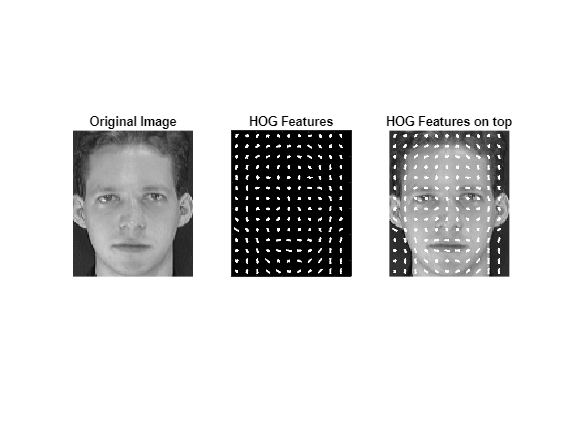


% 3. Display HOG Features
subplot(1, 3, 3);
imshow(img);
hold on;      
plot(hogVisualization); 
title(sprintf('HOG Features on top', cellSize(1), cellSize(2)));
hold off
subplot(1, 3, 2); 
plot(hogVisualization); title('HOG Features')


%[hogFeatures, hogVisualization] = extractHOGFeatures(grayImg, 'CellSize', [4 4]);
%subplot(1, 4, 4); 
%plot(hogVisualization); 


SIFT features

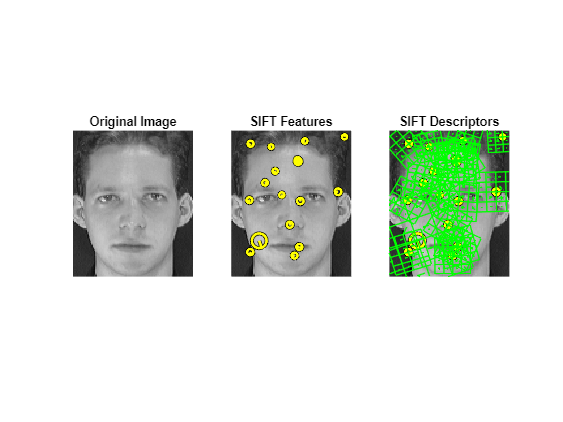

clear;
clc;
close all;
run('C:\Users\Bruger\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\vlfeat-0.9.21\toolbox\vl_setup.m');
imagePath = 'C:\Users\Bruger\Desktop\DSP\project_AT_dataset\archive\s1\1.pgm';
img = imread(imagePath);
figure;
subplot(1, 3, 1);

imshow(img);title('Original Image');
I = single((img)) ;
[f,d] = vl_sift(I) ; 
perm = randperm(size(f,2)) ; 
% We visualize a random selection of 20 features 
sel = perm(1:20) ;
subplot(1, 3, 2); 

imshow(img); title('SIFT Features');
hold on; 
h1 = vl_plotframe(f(:,sel)) ;
h2 = vl_plotframe(f(:,sel)) ;
set(h1,'color','k','linewidth',3) ;
set(h2,'color','y','linewidth',2) ;

subplot(1, 3, 3); 

imshow(img); title('SIFT Descriptors');
hold on; 
h1 = vl_plotframe(f(:,sel)) ;
h2 = vl_plotframe(f(:,sel)) ;
set(h1,'color','k','linewidth',3) ;
set(h2,'color','y','linewidth',2) ;
h3 = vl_plotsiftdescriptor(d(:,sel),f(:,sel)) ;%overlay the descriptors
set(h3,'color','g') ;

SIFT feature match

clear;
clc;
close all;
run('C:\Users\Bruger\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\vlfeat-0.9.21\toolbox\vl_setup.m');
imagePath1 = 'C:\Users\Bruger\Desktop\DSP\project_AT_dataset\archive\s1\1.pgm';
imagePath2 = 'C:\Users\Bruger\Desktop\DSP\project_AT_dataset\archive\s1\3.pgm';
img1 = imread(imagePath1);
img2 = imread(imagePath2);

I1 = single((img1)) ;
I2 = single((img2)) ;

[f1,d1] = vl_sift(I1) ; 
[f2,d2] = vl_sift(I2) ; 

% Combine images side-by-side
[rows1, cols1] = size(I1);
[rows2, cols2] = size(I2);


[matches, scores] = vl_ubcmatch(d1, d2)

matches =      9    11    13    15    21    22    23    28
    10     6     6     5    13    14     6    18


scores =       113869       55080      107882       32807       77845       29733       78683       18598


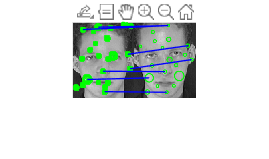


combinedImage = [img1, img2]; % Concatenate images horizontally

f2_adjusted_x = f2(1, :) + cols1;
% --- 5. Display Images and Plot Matches ---
figure;
imshow(combinedImage);
hold on; % Allow plotting over the image

vl_plotframe(f1, 'g.', 'LineWidth', 2);

% For Image 2 (using adjusted x-coordinates)
% Need to manually plot frames since vl_plotframe doesn't take adjusted coords directly
% Plot circles for features in Image 2
radii_b = f2(3,:); % Scale (radius) of SIFT features in Image 2
angles_b = f2(4,:); % Orientation of SIFT features in Image 2
for i = 1:size(f2, 2)
    center = [f2_adjusted_x(i), f2(2, i)];
    radius = radii_b(i);
    % Plot a circle (approximated by an ellipse for visualization of orientation)
    theta = linspace(0, 2*pi, 100);
    x_circle = center(1) + radius * cos(theta);
    y_circle = center(2) + radius * sin(theta);
    plot(x_circle, y_circle, 'g-', 'LineWidth', 1);
end

% Plot matching lines in blue
% Get coordinates of matched features
x1 = f1(1, matches(1,:));
y1 = f1(2, matches(1,:));

x2_original = f2(1, matches(2,:));
y2_original = f2(2, matches(2,:));

% Adjust x2 coordinates for plotting on the combined image
x2_adjusted = x2_original + cols1;

% Plot lines connecting matched points
for i = 1:size(matches, 2)
    line([x1(i), x2_adjusted(i)], [y1(i), y2_original(i)], 'Color', 'b', 'LineWidth', 1);
end